# Process Identification of an ARX Model

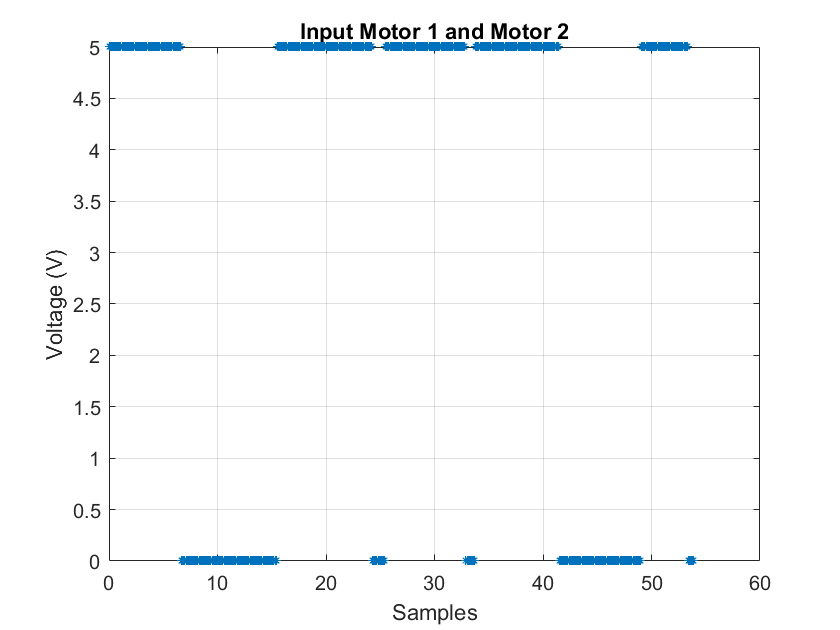

Data = xlsread("C:\Users\rodri\Documents\PY4E\Control\Reto_Control\Motor_Data\PRBS_datos_excel.xlsx");

t = Data(:,1);
U = Data(:,2);
Y_1 = Data(:,5);
Y_2 = Data(:,6);


plot(t,U,'*','MarkerSize',4)
title('Input Motor 1 and Motor 2');
ylabel('Voltage (V)');
xlabel('Samples');
grid on

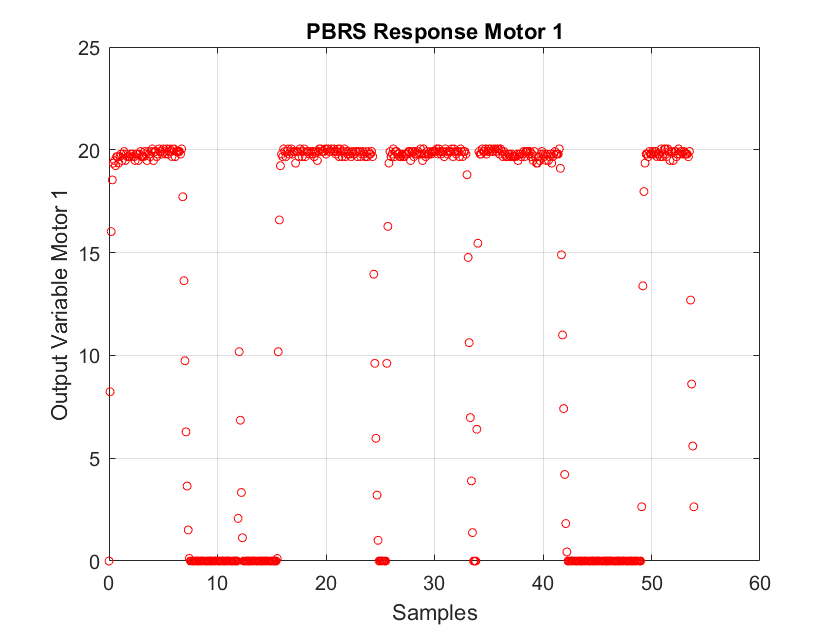


plot(t,Y_1,'o r', 'MarkerSize', 4)
title('PBRS Response Motor 1')
ylabel('Output Variable Motor 1')
xlabel('Samples')
grid on

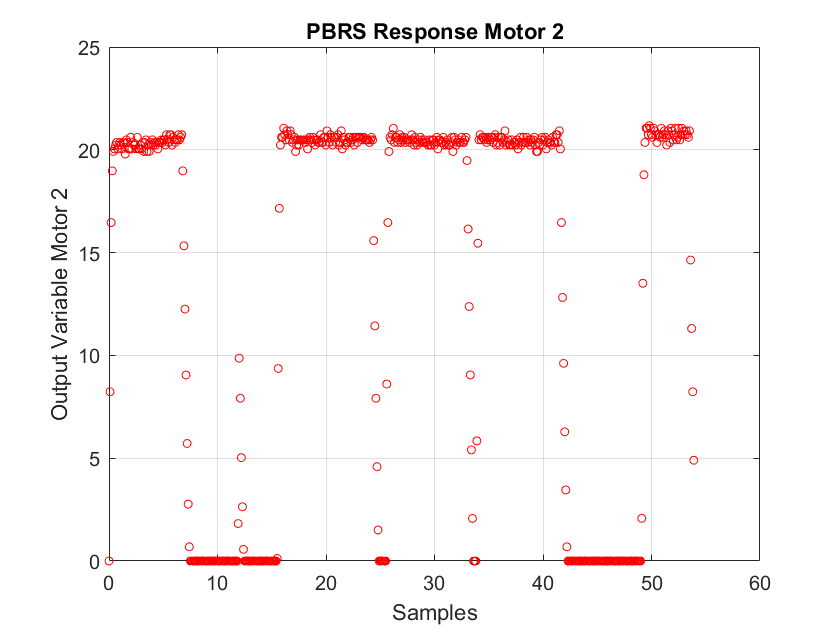


plot(t,Y_2,'o r', 'MarkerSize', 4)
title('PBRS Response Motor 2')
ylabel('Output Variable Motor 2')
xlabel('Samples')
grid on

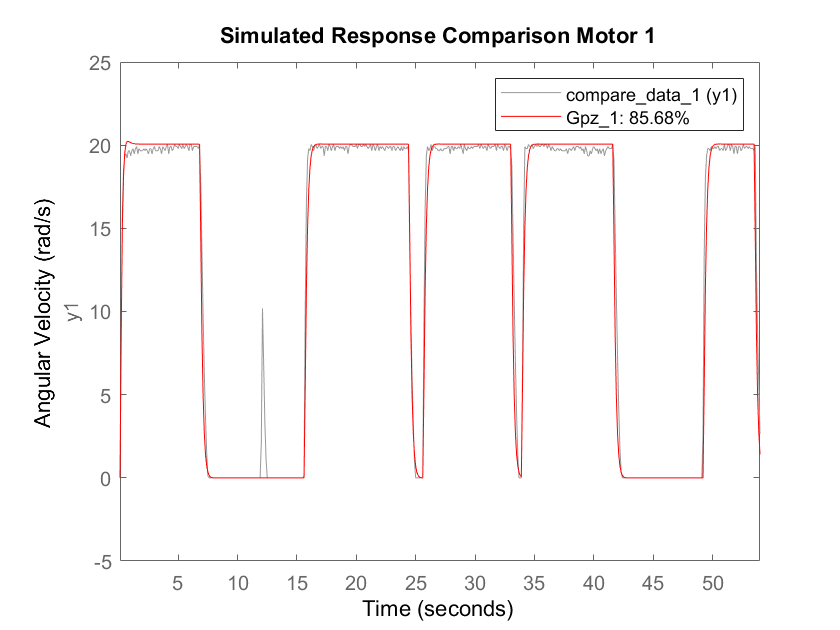


% Motor 1

N = length(Y_1);

%
X=[-[0;Y_1(1:N-1)], -[0;0;Y_1(1:N-2)], [0;U(1:N-1)],[0;0;U(1:N-2)], [0;0;0;U(1:N-3)]];

%Covariance Matrix
Q = X'*X;

%Vector of parameters
Theta = inv(Q)*X'*Y_1;

a1 = Theta(1);
a2 = Theta(2);
b0 = Theta(3);
b1 = Theta(4);
b2 = Theta(5);

z = tf('z', 0.1);
Gpz_1 = ((b0*z^(2)+b1*z+b2)/(z^2+a1*z+a2))*z^(-1);

compare_data_1 = iddata(Y_1, U, 0.1);
compare(compare_data_1, Gpz_1,'r');
title('Simulated Response Comparison Motor 1')
ylabel('Angular Velocity (rad/s)')

Ymodel_1 = predict(Gpz_1,compare_data_1);

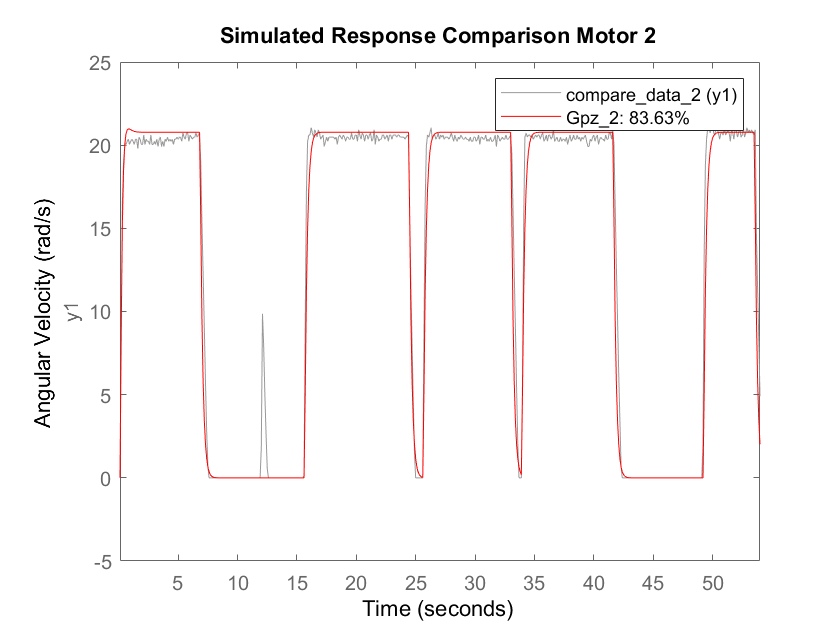


%Motor2
N = length(Y_2);

%
X=[-[0;Y_2(1:N-1)], -[0;0;Y_2(1:N-2)], [0;U(1:N-1)],[0;0;U(1:N-2)], [0;0;0;U(1:N-3)]];

%Covariance Matrix
Q = X'*X;

%Vector of parameters
Theta = inv(Q)*X'*Y_2;

a1 = Theta(1);
a2 = Theta(2);
b0 = Theta(3);
b1 = Theta(4);
b2 = Theta(5);

z = tf('z', 0.1);
Gpz_2 = ((b0*z^(2)+b1*z+b2)/(z^2+a1*z+a2))*z^(-1);

compare_data_2 = iddata(Y_2, U, 0.1);
compare(compare_data_2, Gpz_2,'r');
title('Simulated Response Comparison Motor 2')
ylabel('Angular Velocity (rad/s)')

Ymodel_2 = predict(Gpz_2,compare_data_2);


% Motor 1 
%Covariance in the measurments
fprintf('\n Motor 1:')


 Motor 1:

Gpz_1

Gpz_1 =
 
  1.097 z^2 + 0.008093 z - 0.1973
  -------------------------------
    z^3 - 1.073 z^2 + 0.2992 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Sy_1 = sum((Y_1-mean(Y_1)).^2)

Sy_1 = 4.4295e+04

Sr_1 = sum((Y_1-Ymodel_1.OutputData).^2)

Sr_1 = 908.5691

R2_1 = (Sy_1 - Sr_1)/Sy_1

R2_1 = 0.9795


% Motor 2
%Covariance in the measurments
fprintf('\n Motor 2:')


 Motor 2:

Gpz_2

Gpz_2 =
 
  1.033 z^2 - 0.004355 z - 0.2917
  -------------------------------
     z^3 - 1.171 z^2 + 0.348 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Sy_2 = sum((Y_2-mean(Y_2)).^2)

Sy_2 = 4.6815e+04

Sr_2 = sum((Y_2-Ymodel_2.OutputData).^2)

Sr_2 = 1.2552e+03

R2_2 = (Sy_2 - Sr_2)/Sy_2

R2_2 = 0.9732